
clear; 

data_repo = 'C:\Users\bugeon\Documents\GitHub\Survey/Data';
code_repo = 'C:\Users\bugeon\Documents\GitHub\Survey/Code';
survey_table = 'SurveyResults_curated.xlsx';
feedback_survey_table = 'workshop_feedback_curated.xlsx';
addpath(data_repo);
addpath(genpath(code_repo));

data = io.importSurvey(data_repo,survey_table);

Data imported successfully.
The dataset contains 224 rows and 106 columns.


% returns a table with demographic data
[dgs, dgs_labels] = io.parseDGs(data);

% returns a structure with the answers to the questions and labels
% summarising the questions
answ = io.parseQuestions(data);

Found Import_ and Estab_ 
Found Import__1 and Estab__1 
Found Import__2 and Estab__2 
Found Import__3 and Estab__3 
Found Import__4 and Estab__4 
Found Import__5 and Estab__5 
Found Import__6 and Estab__6 
Found Import__7 and Estab__7 
Found Import__8 and Estab__8 
Found Import__9 and Estab__9 
Found Import__10 and Estab__10 
Found Import__11 and Estab__11 
Found Import__12 and Estab__12 
Found Import__13 and Estab__13 
Found Import__14 and Estab__14 
Found Import__15 and Estab__15 
Found Import__16 and Estab__16 
Found Import__17 and Estab__17 
Found Import__18 and Estab__18 
Found Import__19 and Estab__19 
Found Import__20 and Estab__20 
Found Import__21 and Estab__21 
Found Import__22 and Estab__22 
Found Import__23 and Estab__23 
Found Import__24 and Estab__24 
Found Import__25 and Estab__25 
Found Import__26 and Estab__26 
Found Import__27 and Estab__27 
Found Import__28 and Estab__28 
Found Import__29 and Estab__29 


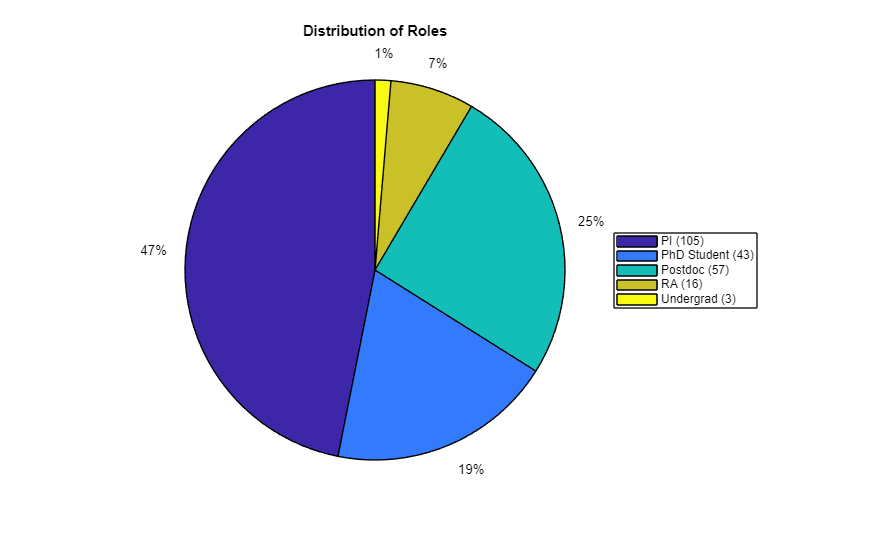

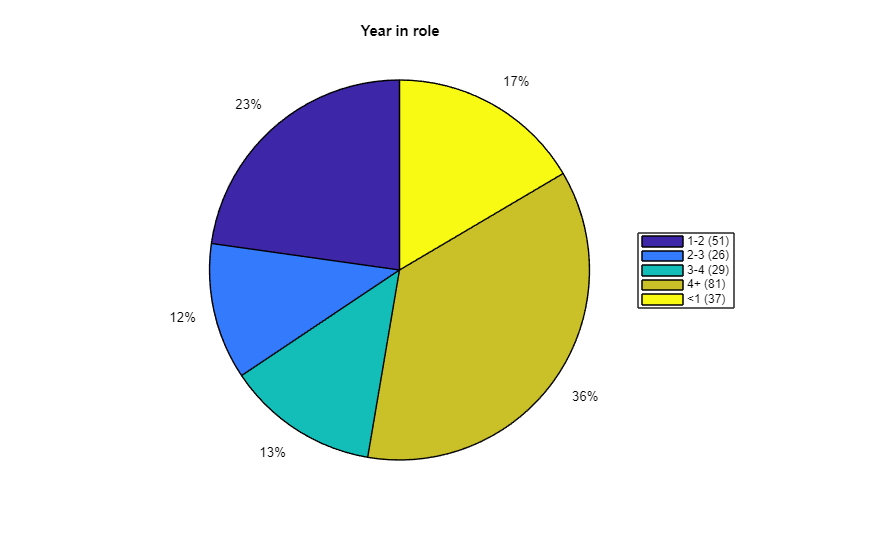

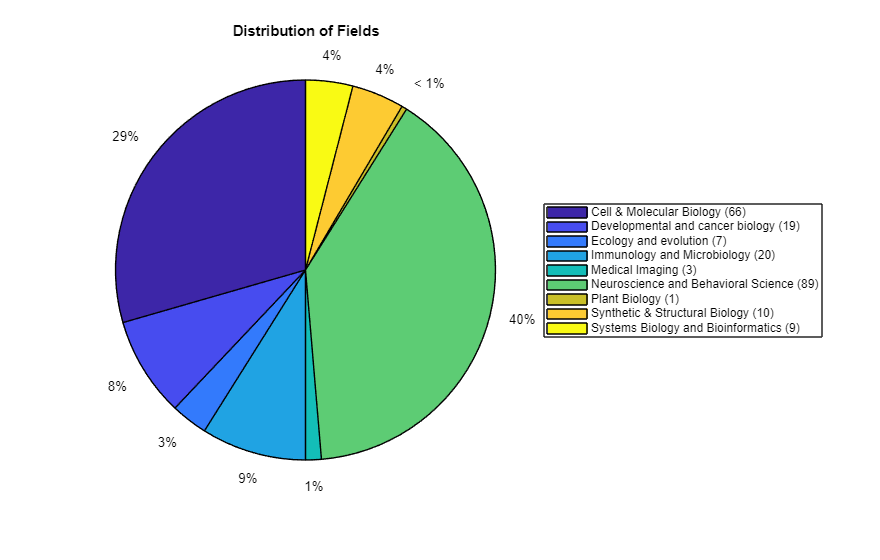

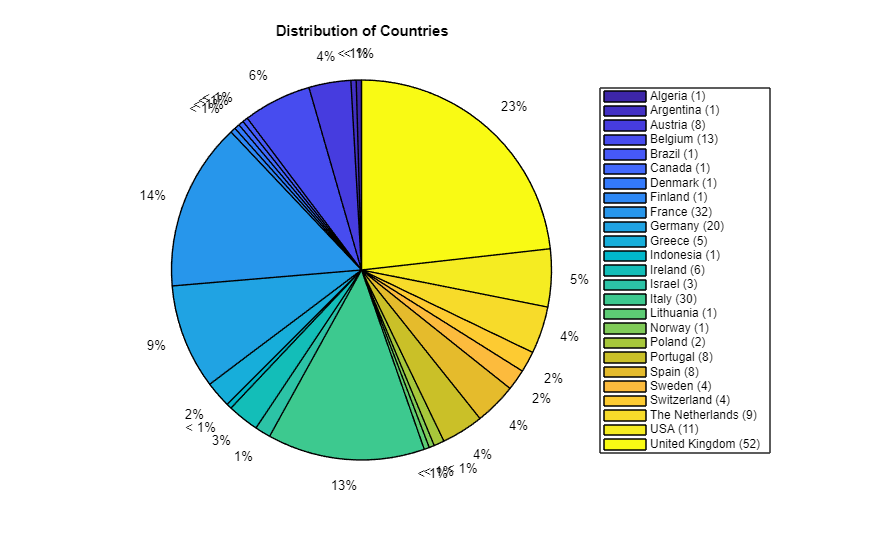

%% Do some basic plotting
options.Sort = 1;
% plots pie charts with demographics
plt.dgspie(dgs);

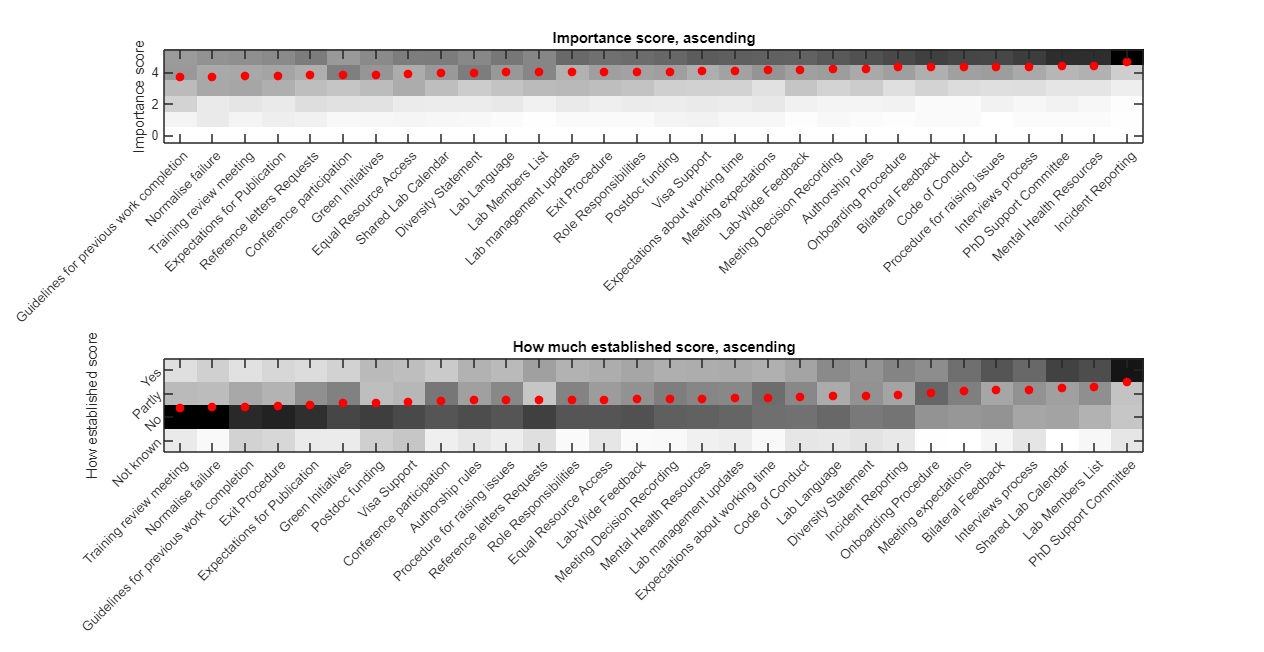

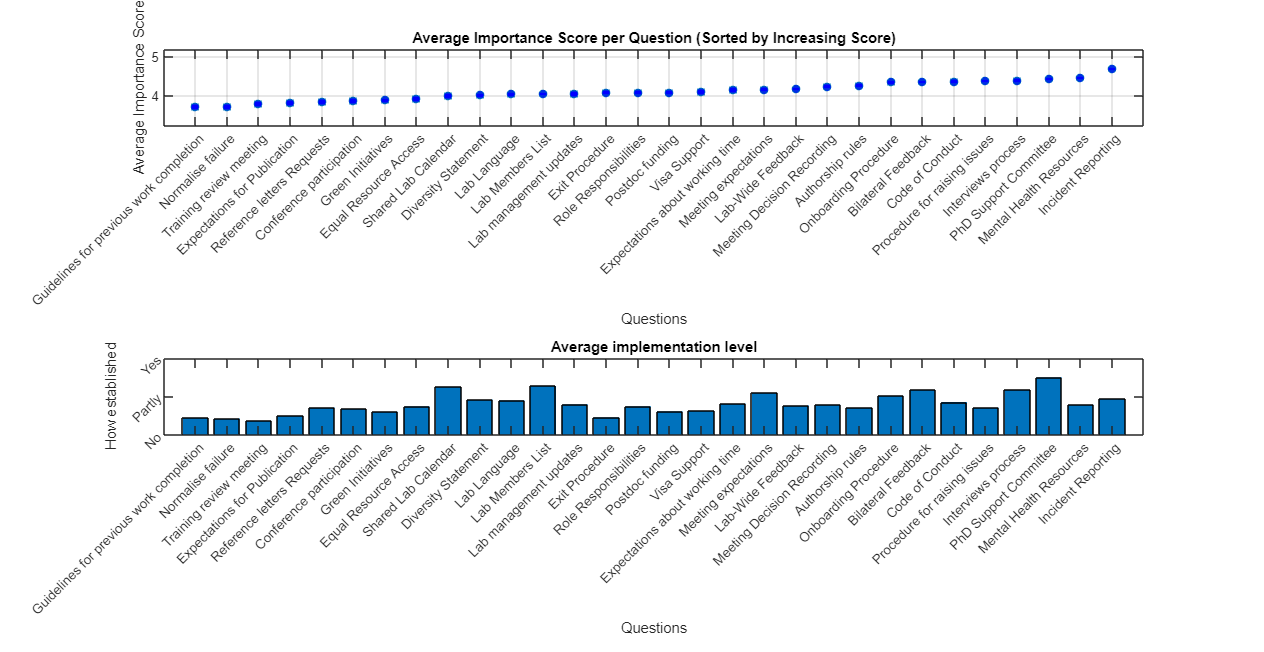

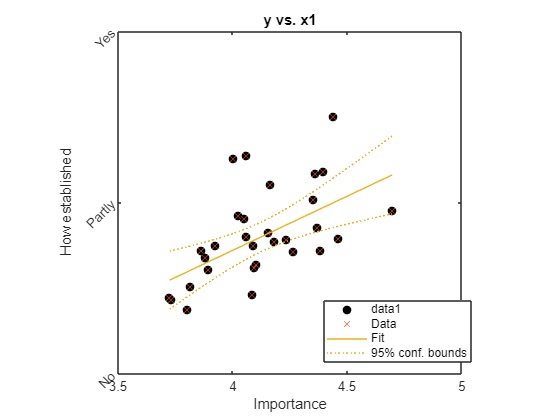

% plots histograms and distributions of answers

[sorted_imp_indices,sorted_est_indices] = plt.anshist(answ);

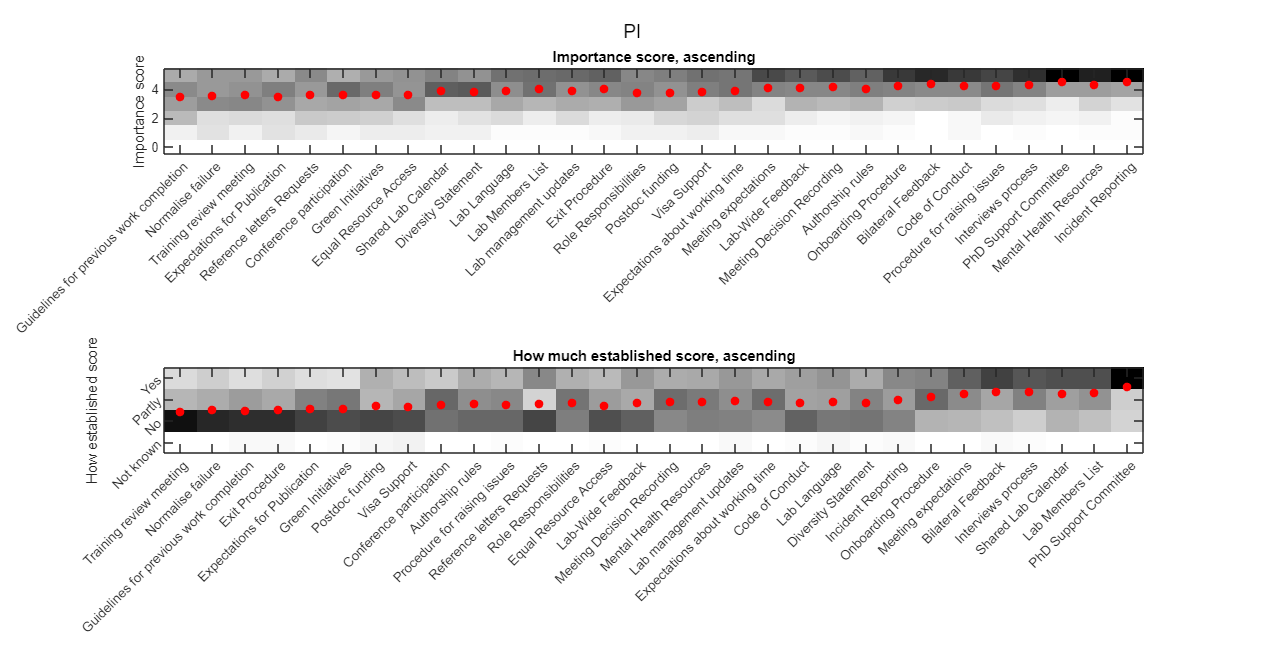

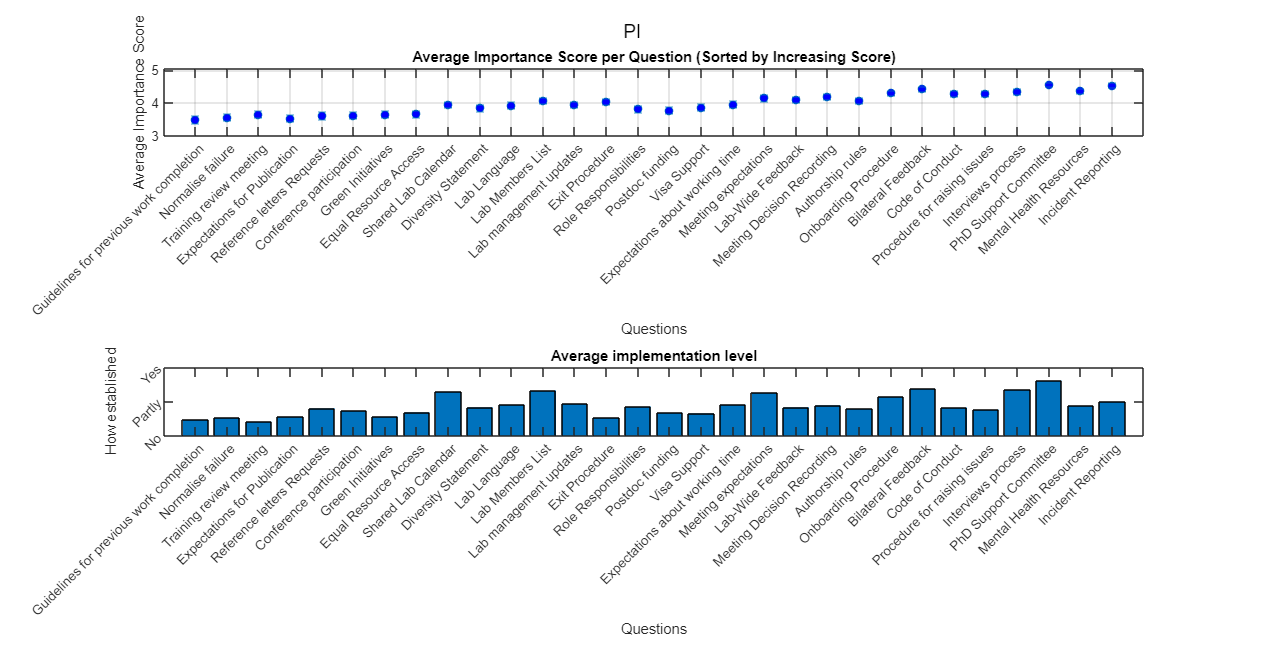

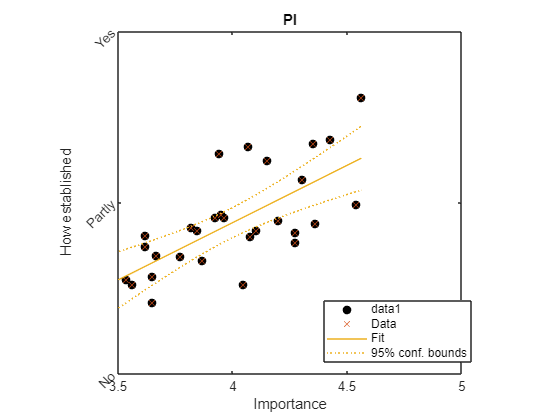

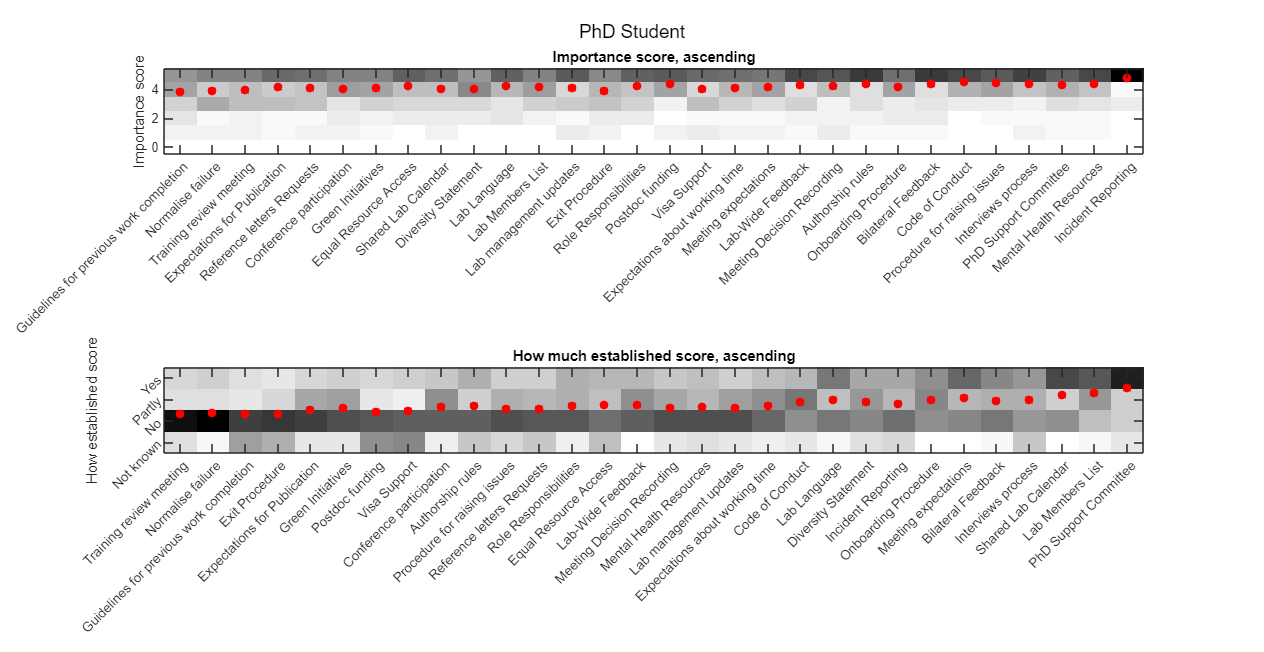

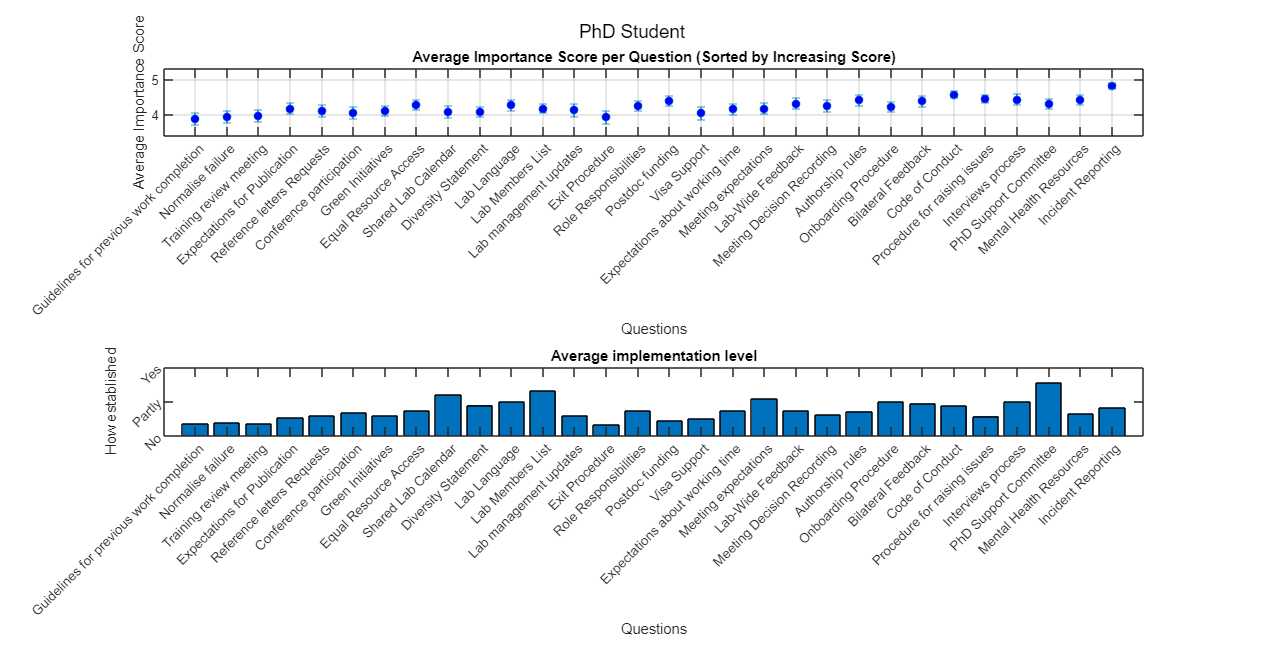

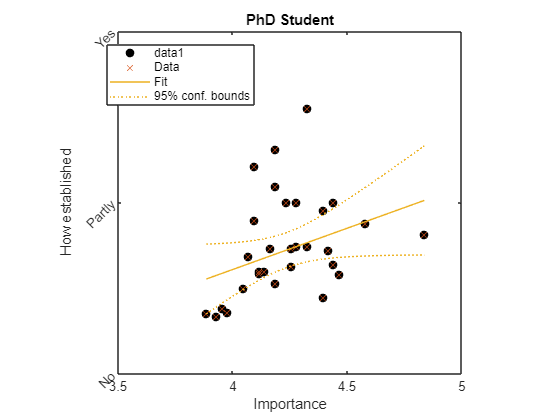

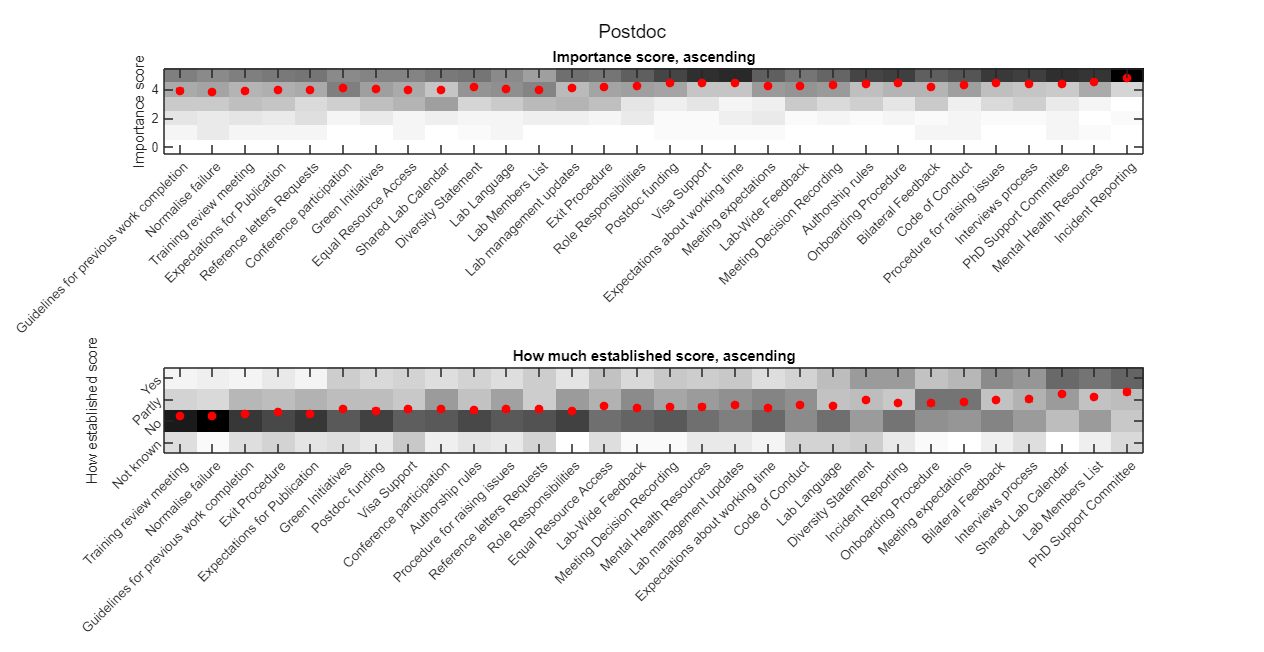

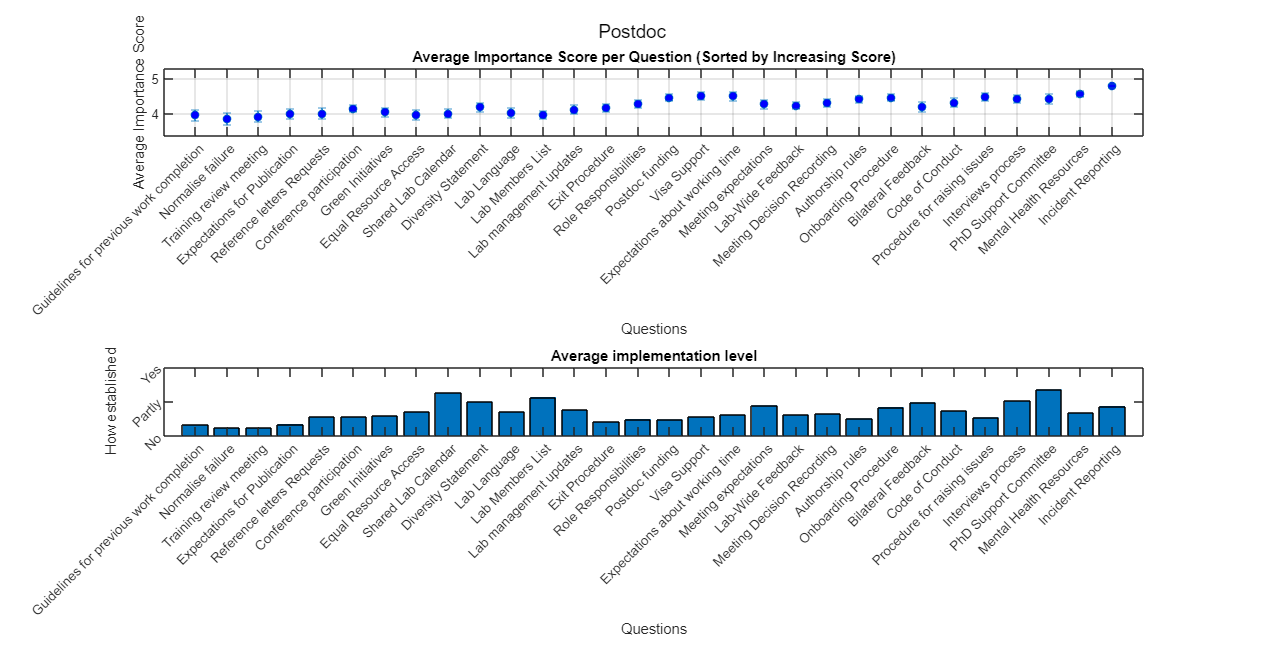

% split histograms by role
plt.anshist(answ,dgs, 'CurrentRole', {'PI' ; 'PhD Student' ; 'Postdoc'},sorted_imp_indices,sorted_est_indices);

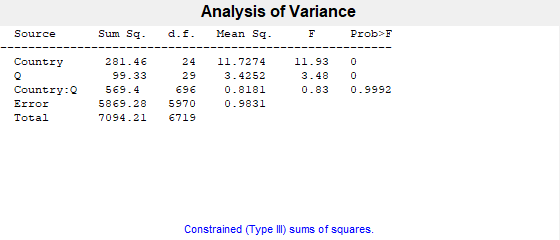

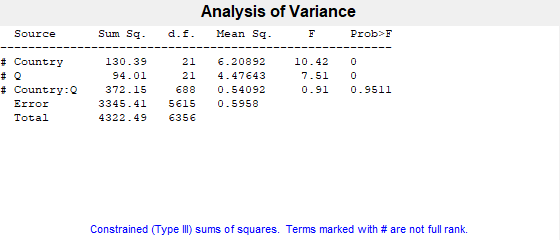

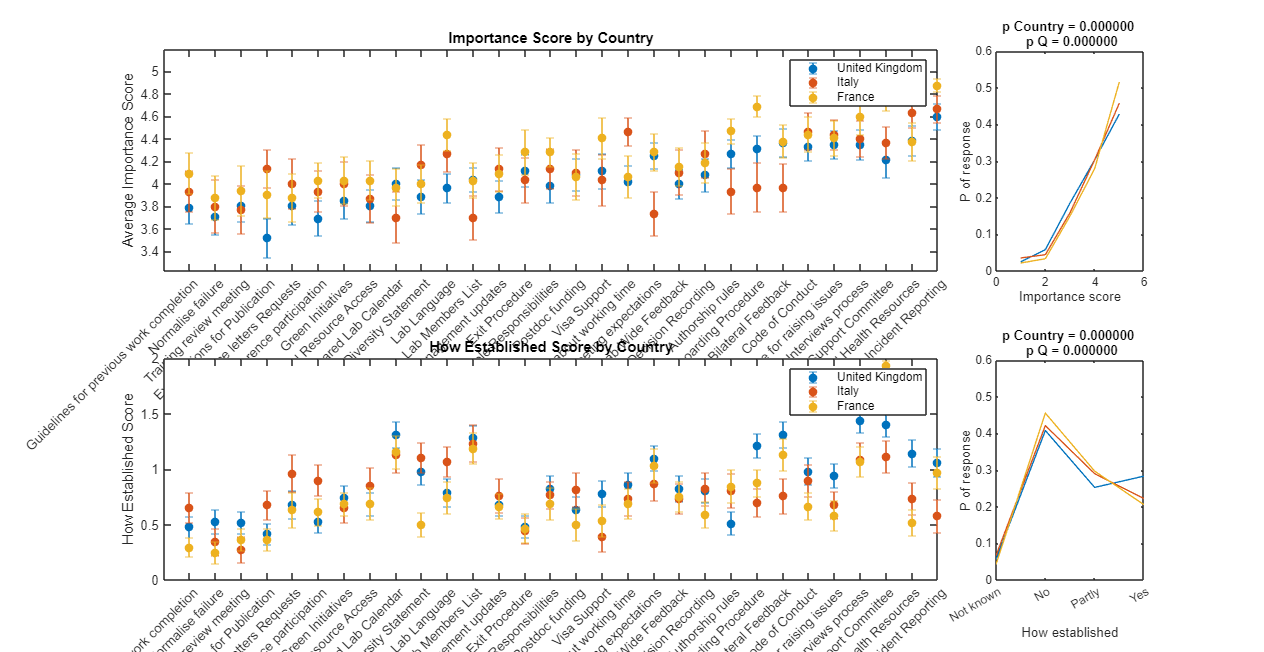

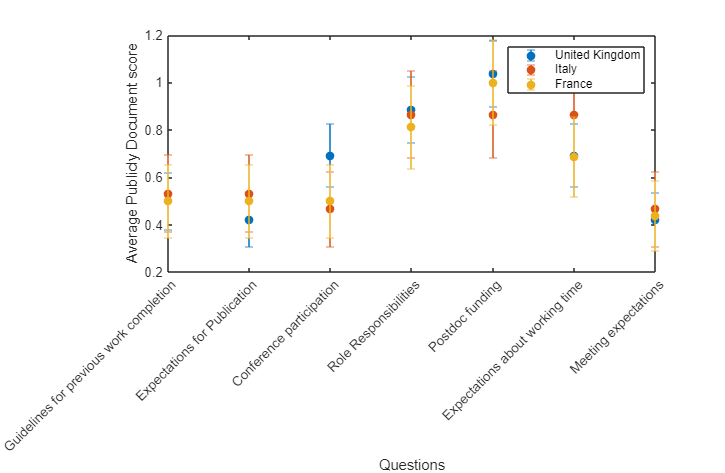

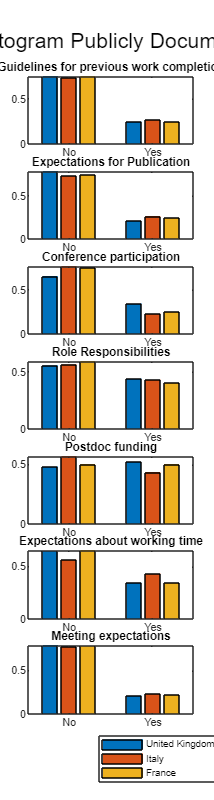

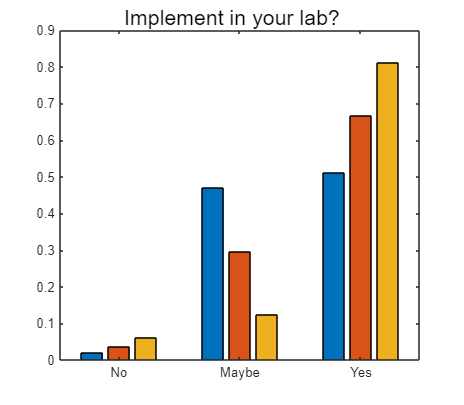

% plots histograms divided by demographic category of choice. You can
% select which categories to plot for clarity
plt.ansbycat(answ, dgs, 'Country', {'United Kingdom' ; 'Italy' ; 'France'});

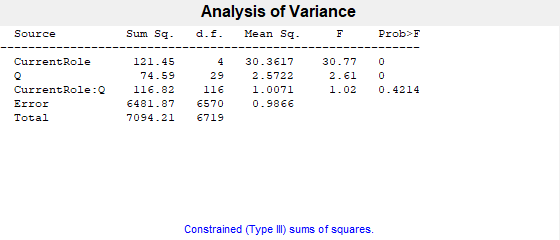

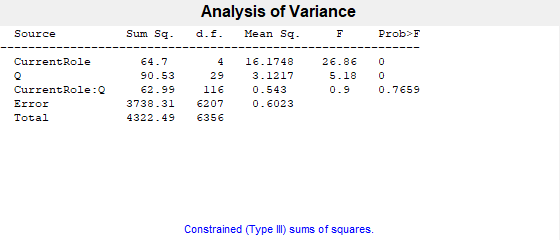

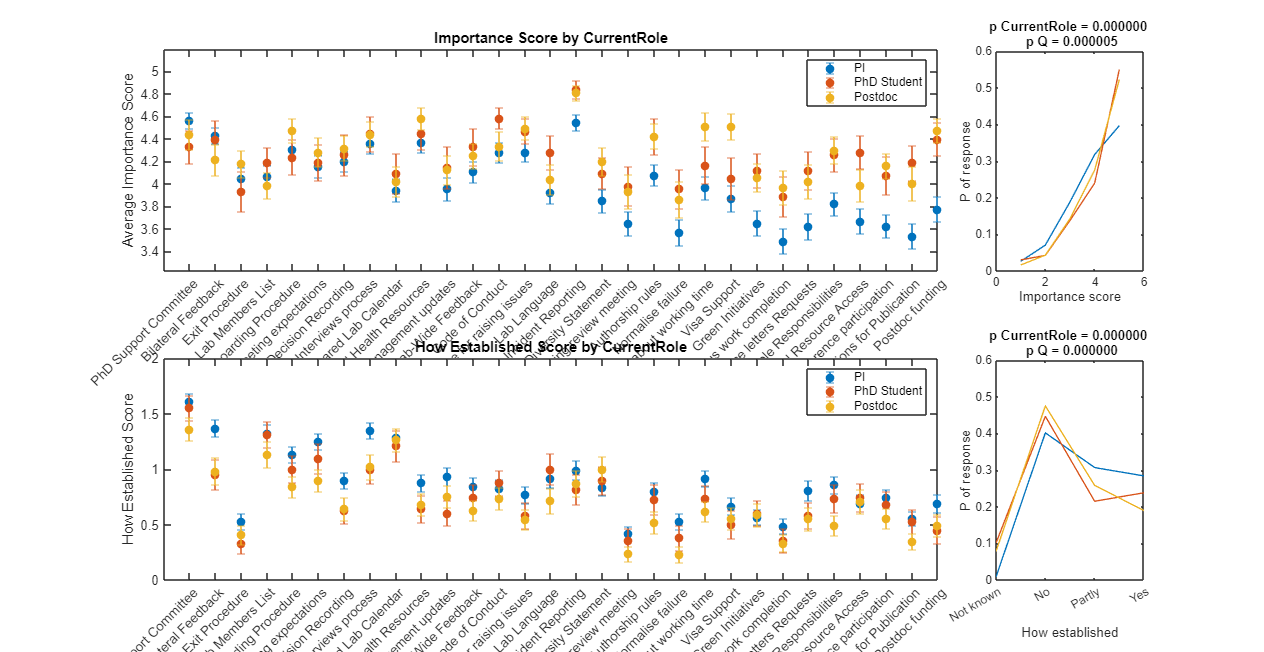

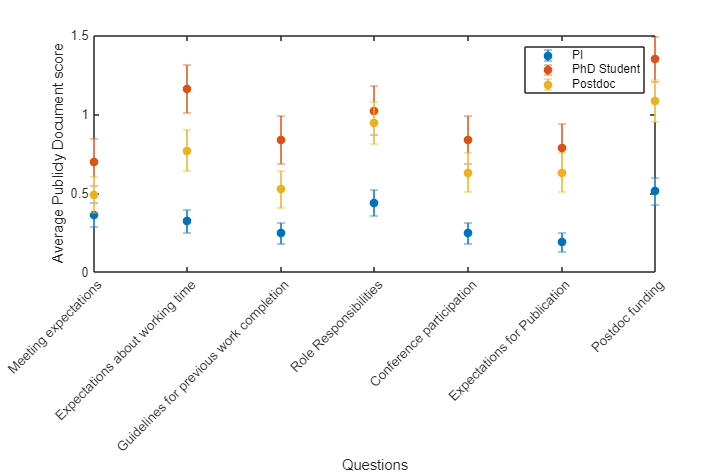

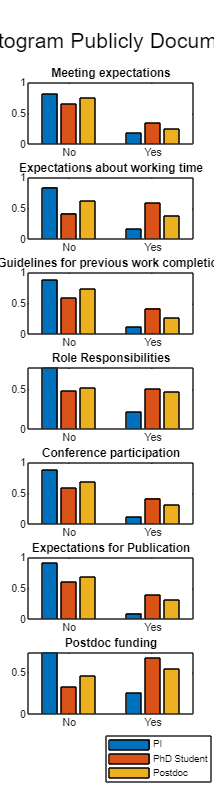

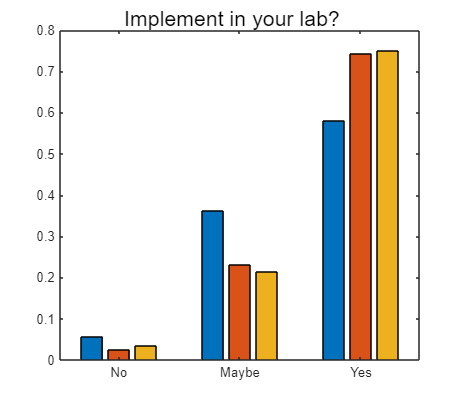

plt.ansbycat(answ, dgs, 'CurrentRole', {'PI' ; 'PhD Student' ; 'Postdoc'}, options);

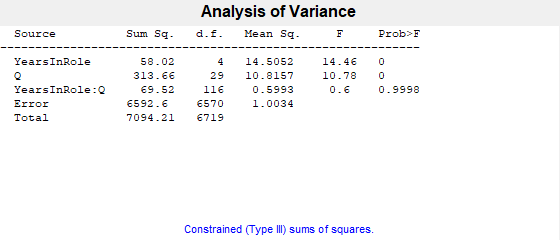

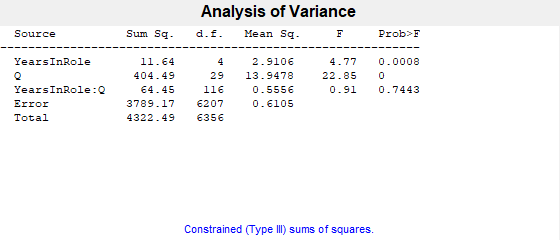

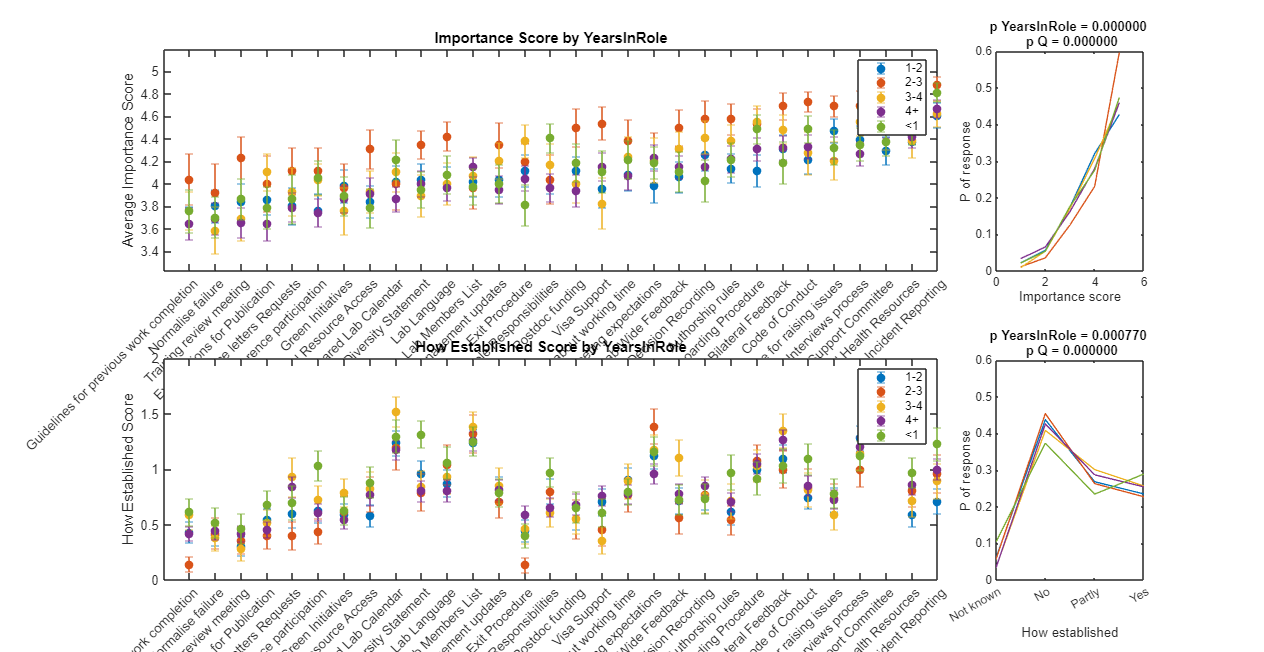

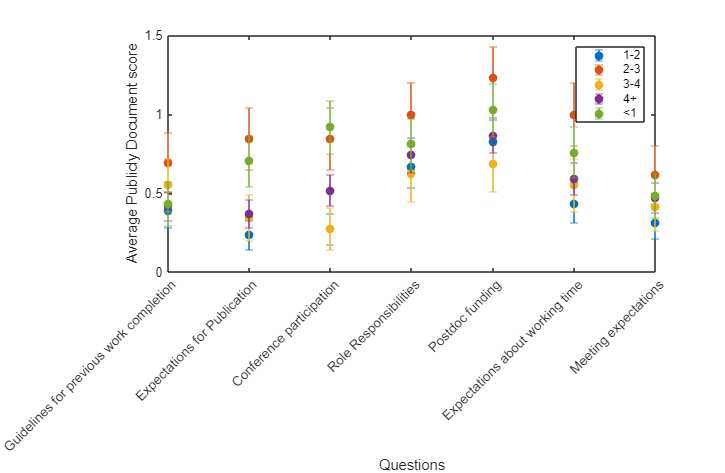

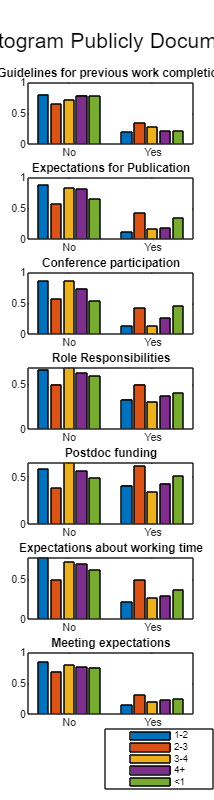

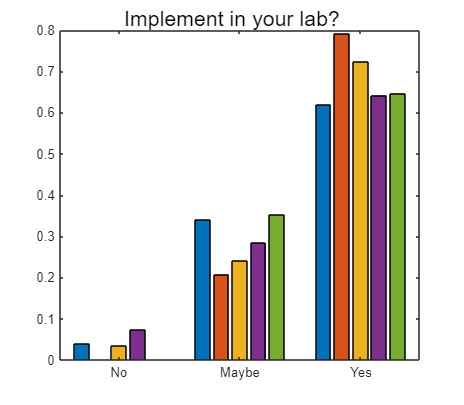

plt.ansbycat(answ, dgs, 'YearsInRole');

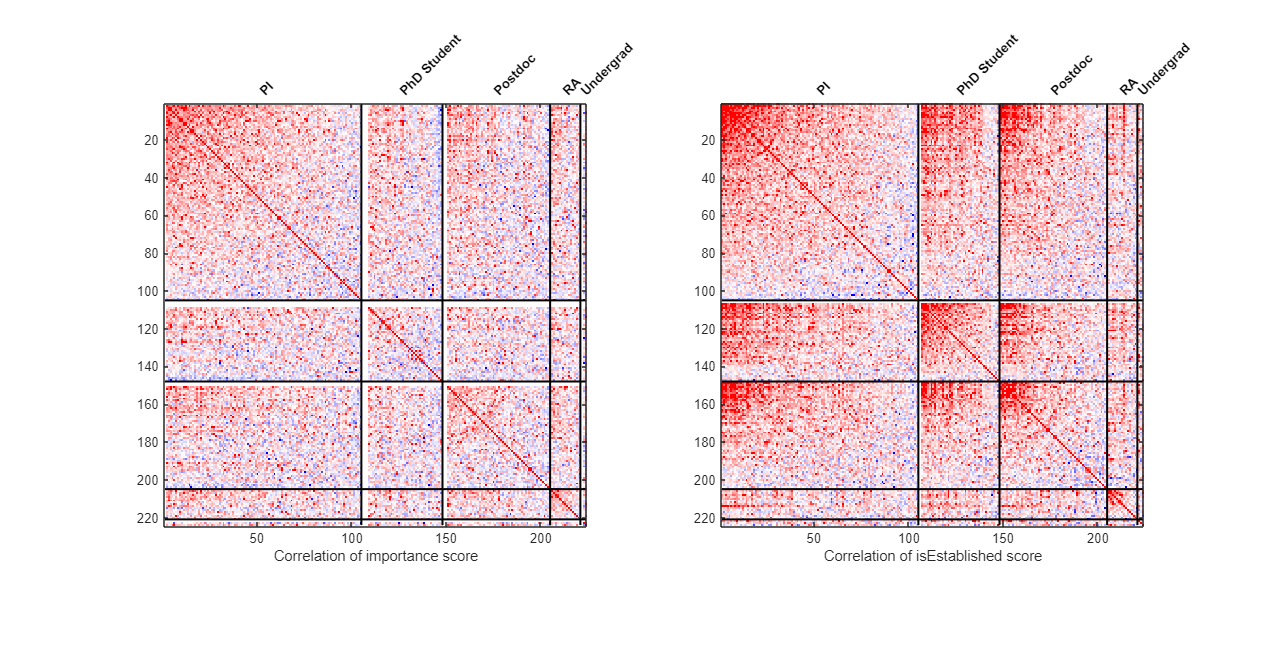

% plots correlation of answers split by demographic category. 
plt.answcorr(answ, dgs, 'CurrentRole');

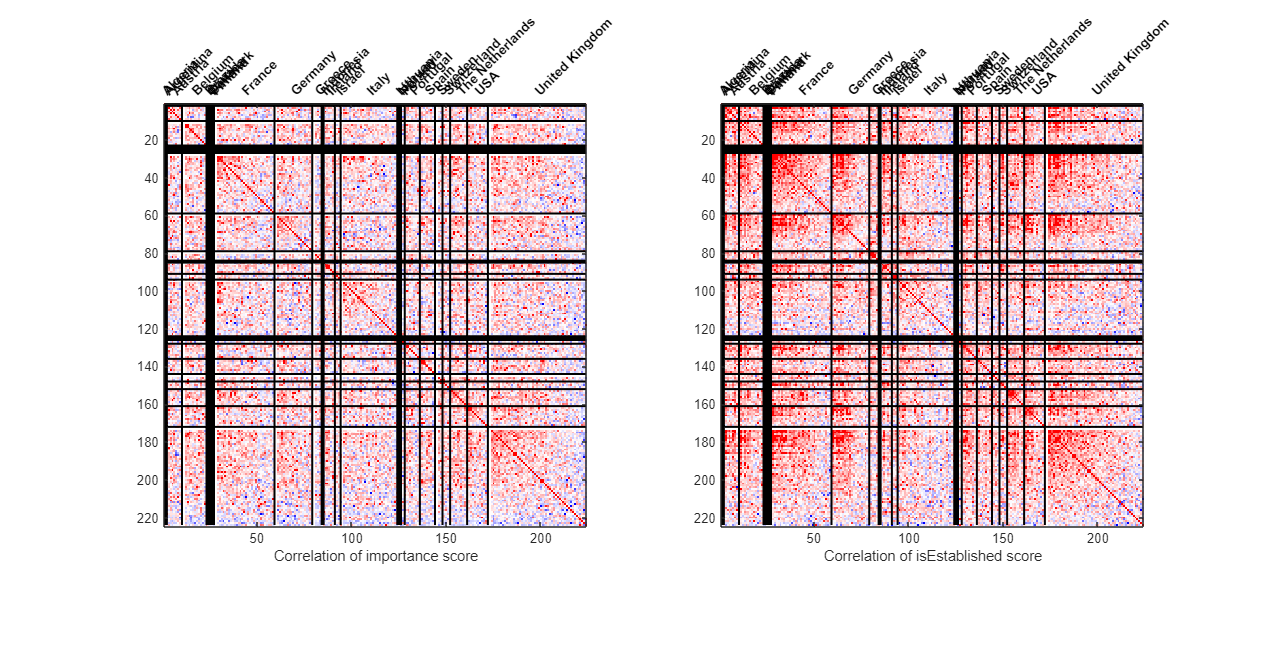

plt.answcorr(answ, dgs, 'Country');

Parallelizing UMAP with MATLAB's 24 assigned logical cores for nn_descent_tasks, sgd_tasks
UMAP(method=Java, n_neighbors=7, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.1, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=1.57694357028599, b=0.895060673920128, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]
  Computing fuzzy simplicial set (224 x 30 values)


  Computing embedding (224 x 30 values)
0/500 epochs done
25/500 epochs done
50/500 epochs done
75/500 epochs done
100/500 epochs done
125/500 epochs done
150/500 epochs done
175/500 epochs done
200/500 epochs done
225/500 epochs done
250/500 epochs done
275/500 epochs done
300/500 epochs done
325/500 epochs done
350/500 epochs done
375/500 epochs done
400/500 epochs done
425/500 epochs done
450/500 epochs done
475/500 epochs done
500/500 epochs done
UMAP(method=Java, n_neighbors=7, n_components=2, metric='euclidean', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.1, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=1.57694357028599, b=0.895060673920128, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]
  Computing fuzzy simplicial set (224

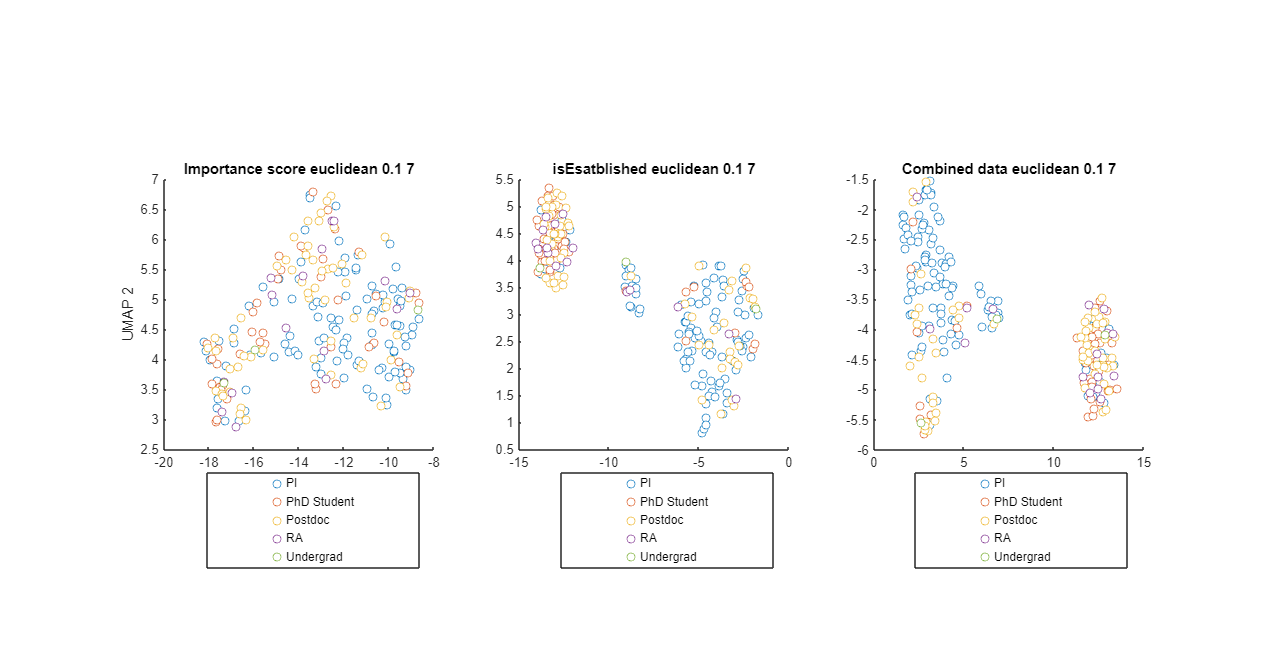

% UMAP projection of data (still playing with pars)
plt.UMAPproj(answ, dgs, 'CurrentRole', {'euclidean', 0.1, 7});

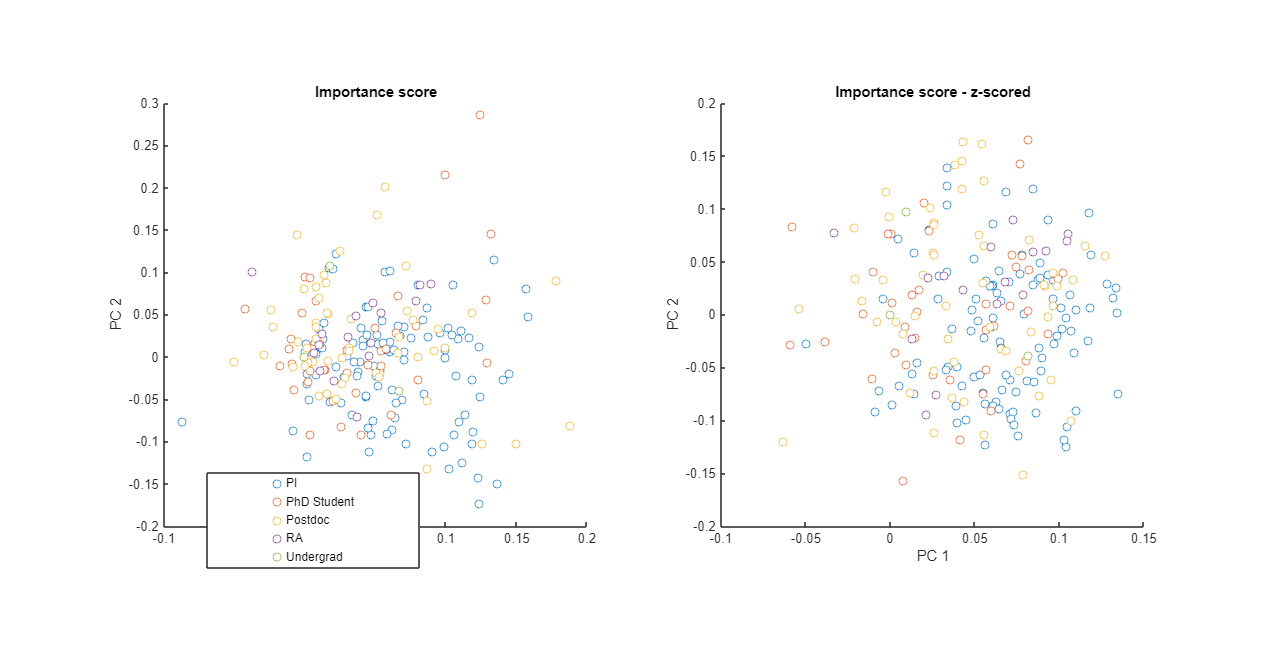

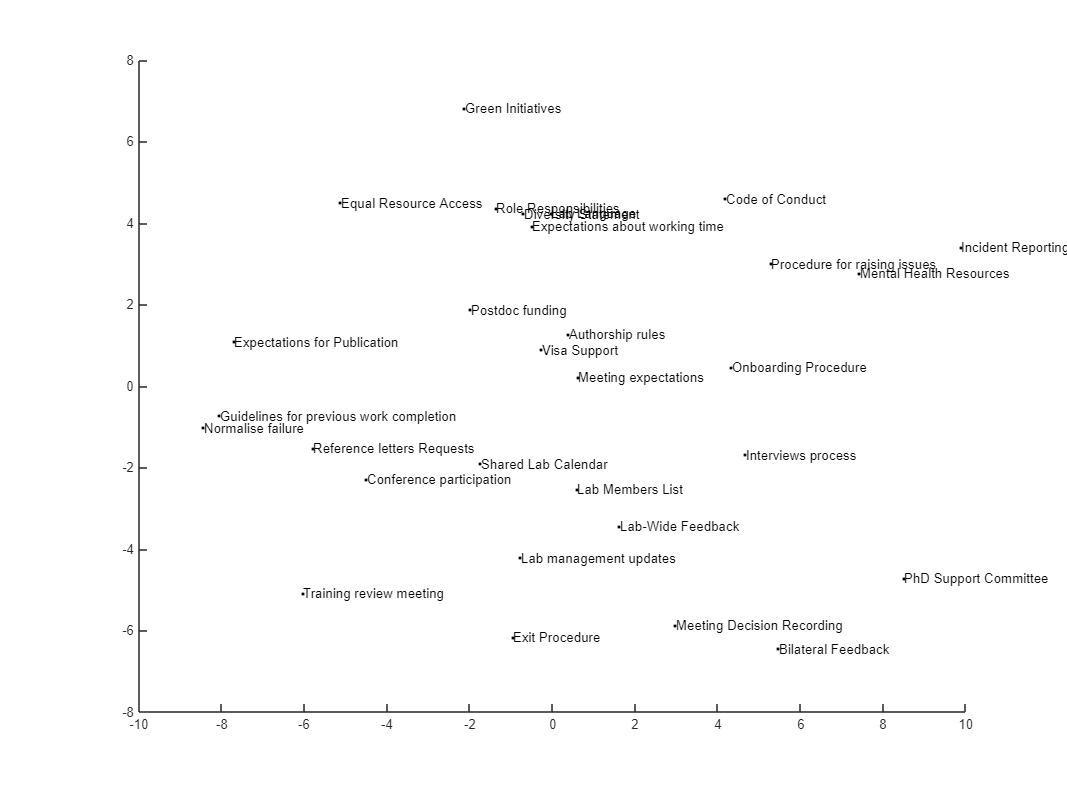

% PCA projection of data
plt.PCAproj(answ, dgs, 'CurrentRole')

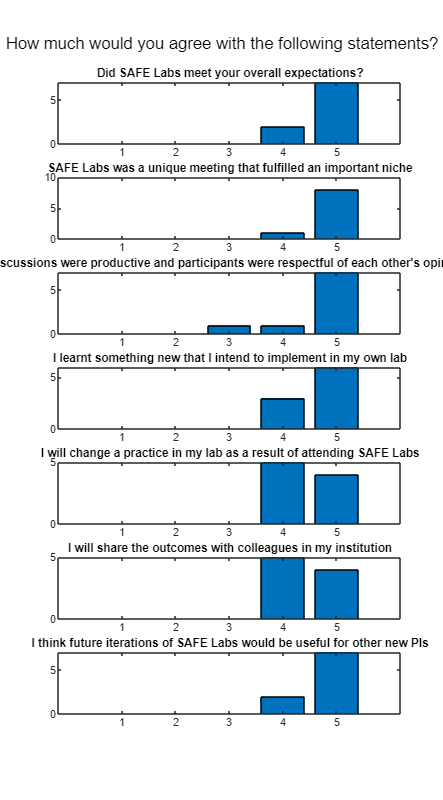

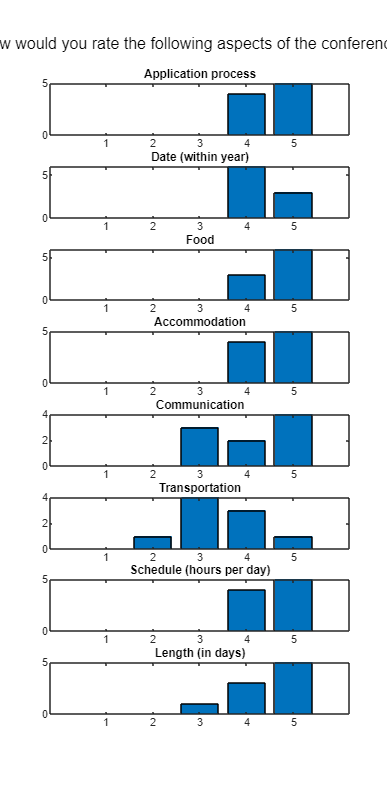

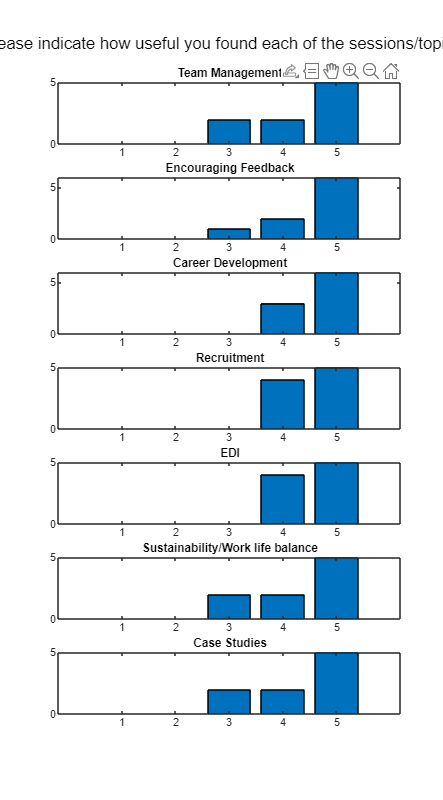

%% SAFE labs meeting 2024 - feedback survery results
plt.feedbackSummary(data_repo,feedback_survey_table)